% PHYS 434
% LAB 7 (Event selection optimization)
% Jin Kyoung Lee

% Importing data
% Signal dataset
h5disp("LAB/Higgs_data/Sample_low_pt/higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgsData = h5read("LAB/Higgs_data/Sample_low_pt/higgs_100000_pt_250_500.h5","/higgs_100000_pt_250_500");
% Background dataset
h5disp("LAB/Higgs_data/Sample_low_pt/qcd_100000_pt_250_500.h5")

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcdData = h5read("LAB/Higgs_data/Sample_low_pt/qcd_100000_pt_250_500.h5","/qcd_100000_pt_250_500");

% The training data containes 14 features:
% pt, eta, phi, mass, ee2, ee3, d2, angularity, t1, t2, t3, t21, t32, KitDeltaR

## 1.

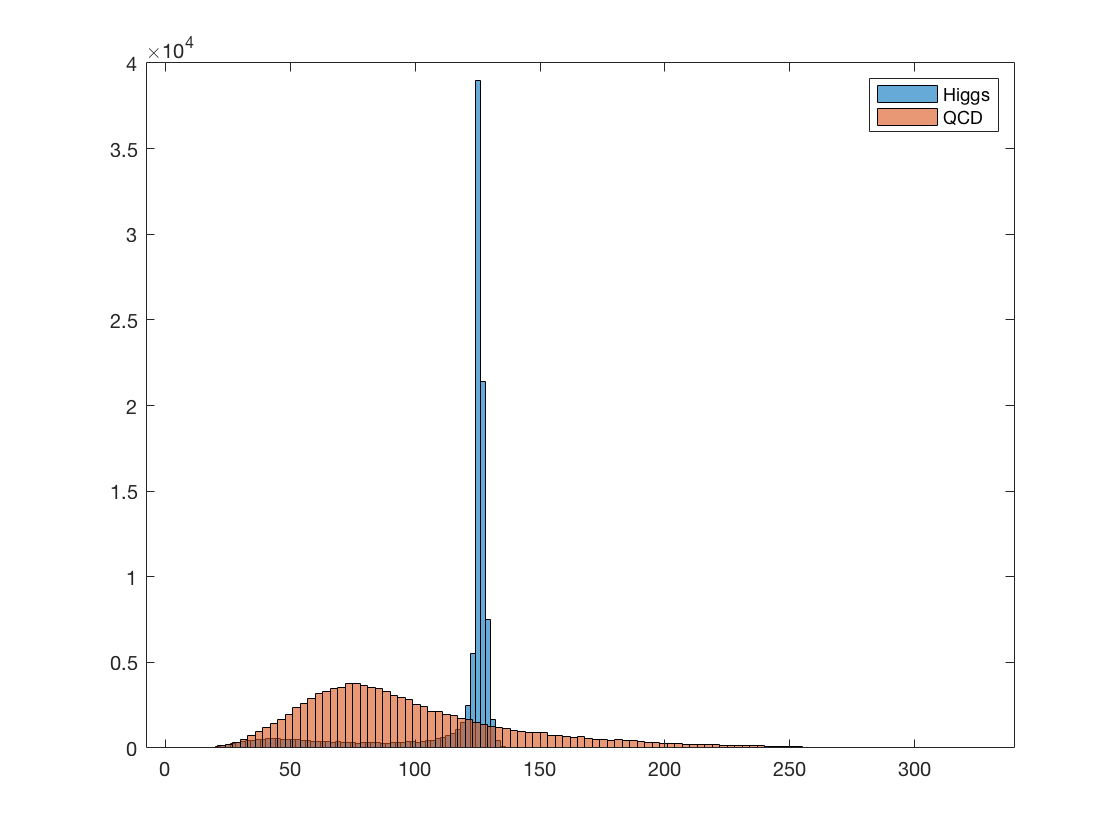

% Histogram for the feature variable: mass
% Higgs (N0_higgs = 100)
massHiggs = higgsData(4,1:100000);
histogram(massHiggs,'DisplayStyle','bar')
hold on
% QCD (N0_qcd = 20000)
massQCD = qcdData(4,1:100000);
histogram(massQCD,'DisplayStyle','bar')
legend ("Higgs","QCD")
hold off

% Higgs expected significance:
N0_higgs = 100;
% QCD expected significance:
N0_qcd = 20000;
size = 100000;
higgsPoiss = poissrnd(N0_higgs,1,size);
qcdPoiss = poissrnd(N0_qcd,1,size);
totalPoiss = higgsPoiss + qcdPoiss;
%{
histogram(higgsPoiss,'DisplayStyle','bar')
histogram(qcdPoiss,'DisplayStyle','bar')
histogram(totalPoiss,'DisplayStyle','bar')
%}
N_tot = mean(totalPoiss)

N_tot = 2.0100e+04

## 2

cutsMax = 100;
cuts = zeros(100000,1);
for i = 1:100000
    cuts(i) = massHiggs(i);
    if (cuts(i)<=cutsMax)
        massHiggsCuts = cuts(cuts<=cutsMax);
    end
end

N_higgs_select_range = mean(massHiggsCuts)

N_higgs_select_range = 58.8177

N_higgs_all_range = poissfit(massHiggs,0.001)

N_higgs_all_range = 114.8924

N0_higgs * (N_higgs_select_range / N_higgs_all_range)

ans = 51.1937

cutsMax = 100;
cuts = zeros(100000,1);
for i = 1:100000
    cuts(i) = massQCD(i);
    if (cuts(i)<=cutsMax)
        massQCDCuts = cuts(cuts<=cutsMax);
    end
end

N_QCD_select_range = mean(massQCDCuts)

N_QCD_select_range = 70.7296

N_QCD_all_range = poissfit(massQCD,0.001)

N_QCD_all_range = 97.7380

N0_qcd * (N_QCD_select_range / N_QCD_all_range)

ans = 1.4473e+04